Q = 1.0e+11 *

    1.1185    0.0241         0
    0.0241    0.0820         0
         0         0    0.0416


layup =     45   -45     0    90     0    90     0   -45    45


Q_45 = 1.0e+10 *

    3.5377    2.7061    2.5911
    2.7061    3.5377    2.5911
    2.5911    2.5911    2.8807


Q_neg45 = 1.0e+10 *

    3.5377    2.7061   -2.5911
    2.7061    3.5377   -2.5911
   -2.5911   -2.5911    2.8807


Q_0 = 1.0e+11 *

    1.1185    0.0241         0
    0.0241    0.0820         0
         0         0    0.0416


Q_90 = 1.0e+11 *

    0.0820    0.0241         0
    0.0241    1.1185         0
         0         0    0.0416


n = 9

h = 1.0e-03 *

    0.4500    0.3500    0.2500    0.1500    0.0500    0.0500    0.1500    0.2500    0.3500    0.4500


z = 1.0e-03 *

   -0.4500   -0.3500   -0.2500   -0.1500   -0.0500    0.0500    0.1500    0.2500    0.3500    0.4500


z1 = 1.0e-03 *

   -0.4000   -0.3000   -0.2000   -0.1000         0         0    0.1000    0.2000    0.3000    0.4000


z1 = 1.0e-03 *

   -0.3000   -0.2000   -0.1000         0    0.1000    0.2000    0.3000


layup =     45   -45     0    90     0    90     0   -45    45


ans =      1     2     3     4     5     6     7     8     9


A = 1.0e+07 *

    4.9346    1.2030         0
    1.2030    3.8982         0
         0         0    1.3602


B = 1.0e-13 *

    0.2842   -0.8527         0
   -0.8527    0.2842         0
         0         0    0.2842


D =     0.2319    0.0690    0.0000
    0.0690    0.2233    0.0000
    0.0000    0.0000    0.0773


eta_0 = 1.0e-03 *

    0.2191
   -0.0676
    0.0000


K = 1.0e-15 *

   -0.0872
    0.1192
   -0.0000


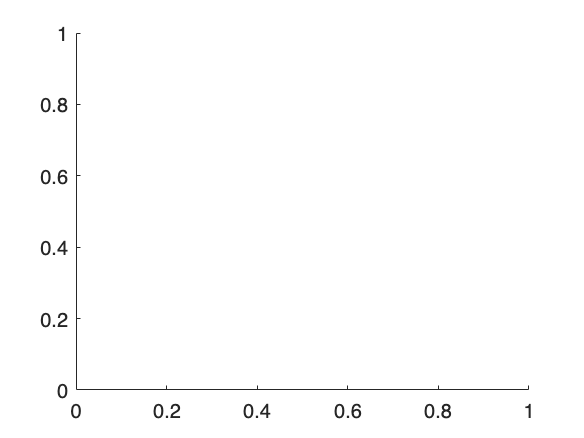

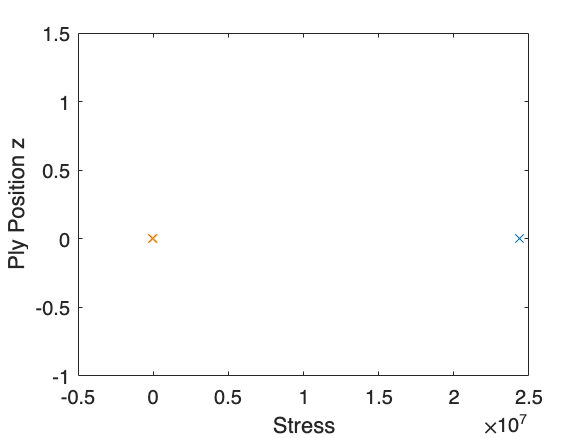

n_0sc =      0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


n_45sc =      0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


n_90sc =      0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


n_45sw =      0     1     1     1     2     2     2     3     3     3     4     4     4     5     5     5     6     6     6     7     7     7     8     8     8     8     9     9     9    10    10    10    11    11


n_0sw =      0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     2     2     2     2     2     2     2     2


n_90sw =      0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     2     2     2     2     2     2     2     2


clear

clc
t=0.125/1000; %mm
Ef=183e9; % http://www.performance-composites.com/carbonfibre/mechanicalproperties_2.asp
Em=3.35e9;
phif=0.6;
phim=1-phif;
vf=0.27;
vm=0.33;
Gf=12e9;
Gm=2.1e9;
E1=phif*Ef+phim*Em;
E2=1/(phif/Ef + phim/Em);
v12=phif*vf+phim*vm;
G12=1/(phif/Gf + phim/Gm);
v21=v12*E2/E1;
Q11=E1/(1-v12*v21);
Q22=E2/(1-v12*v21);
Q12=v12*E2/(1-v12*v21);
Q66=G12;
Q=[Q11 Q12 0; Q12 Q22 0; 0 0 Q66]
A=zeros(3);
B=zeros(3);
D=zeros(3);

%HTP NACA0009 Croot=2.181 Ctip=0.981 Sweep=40
%HTP span 6.325 half span 3.1625
AR=4;
Sref=10;
taper=0.45;
b=sqrt(AR*Sref_h);
s=b*0.5/cosd(17) % Update sweep to flexural axis!!!!!!!
x=linspace(0,s,20)
c_root=2*Sref/(b*(1+taper));
c_tip=taper*c_root;
t=0.125/1000;
Vn=-574.81.*x.^3+886.32.*x.^2+16861.*x-43649; %Shear force along span
BM=590.63.*x.^3-10164.*x.^2+44792.*x-58907; %Bending moment along span
Torque=200.49.*x.^3-2003.2.*x.^2+5678.6.*x-4347.1;
h=0.09.*((c_tip-c_root)/(s).*x +c_root);
b=(0.6-0.15).*((c_tip-c_root)/(s).*x +2.181);
%a=0.25; %rib spacing ish
Nxx=BM./(h.*b);

% sigmaxx=min(abs(stress(1,:)));
% sigmaxy=min(abs(stress(3,:)));
sigmaxx=1500000000;
sigmaxy=80000000;
%cover
n_0sc=abs(ceil(Nxx./(t*sigmaxx))) % 70% %For some reason this aint working
n_45sc=abs(ceil(2.*n_0sc./7)) % 20%
n_90sc=abs(ceil(n_0sc./7)) % 10%
% Gxy=G12;
% T=n*t; 
% gxy=Gf;
%web
n_45sw=abs(ceil(Vn./(h*t*sigmaxy))) % 80%
n_0sw=abs(ceil(n_45sw./8)) % 10%
n_90sw=abs(ceil(n_45sw./8)) % 10%


layup=[45 -45 -45 45]

Q_45=Q_bar(Q11, Q22, Q12, Q66, 45)
Q_neg45=Q_bar(Q11, Q22, Q12, Q66, -45)
Q_0=Q_bar(Q11, Q22, Q12, Q66, 0) %check == Q
Q_90=Q_bar(Q11, Q22, Q12, Q66, 90)
n=length(layup)
% temp=zeros(1,5)
if mod(n,2)==0 %even number of ply
    for i=1:n/2
        temp(i)=i*t;
    end
    h=[-flip(temp) 0 temp]
    z1=[-flip(temp)+t/2 temp-t/2]
else %odd number of ply
    for i=1:n/2 + 0.5
        temp(i)=(i-0.5)*2*t/2;
    end
    h=[-flip(temp) temp]
    z1=[-flip(temp)+t/2 temp-t/2];
    z1=[z1(1:length(z1)/2), z1(length(z1)/2 +2:length(z1))]
end
layup
1:n
for i=1:3
    for j=1:3
        for k=1:n
            if layup(k)==45
                A(i,j)=A(i,j)+Q_45(i,j)*t;
                B(i,j)=B(i,j)+0.5*Q_45(i,j)*(h(k+1)^2 - h(k)^2);
                D(i,j)=D(i,j)+(1/3)*Q_45(i,j)*(h(k+1)^3 - h(k)^3);
            elseif layup(k)==-45
                A(i,j)=A(i,j)+Q_neg45(i,j)*t;
                B(i,j)=B(i,j)+0.5*Q_neg45(i,j)*(h(k+1)^2 - h(k)^2);
                D(i,j)=D(i,j)+(1/3)*Q_neg45(i,j)*(h(k+1)^3 - h(k)^3);
            elseif layup(k)==90
                A(i,j)=A(i,j)+Q_90(i,j)*t;
                B(i,j)=B(i,j)+0.5*Q_90(i,j)*(h(k+1)^2 - h(k)^2);
                D(i,j)=D(i,j)+(1/3)*Q_90(i,j)*(h(k+1)^3 - h(k)^3);
            else
                A(i,j)=A(i,j)+Q_0(i,j)*t;
                B(i,j)=B(i,j)+0.5*Q_0(i,j)*(h(k)^2 - h(k+1)^2);
                D(i,j)=D(i,j)+(1/3)*Q_0(i,j)*(h(k)^3 - h(k+1)^3);
            end
        end
    end
end
A %balanced A16=A26==0
B %symmetric and balanced B==0
D

%Critical buckling load
C=2;
a/b(1)*(D(2)/D(1))^0.25 %get K value from slide 61 (7 Composites)
K_0=20;
D_0=D(1,2)+2*D(3);
Nxb=K_0*(D(1)*D(2))*0.5/(b(1)^2) + C*3.1416^2*D_0/(b(1)^2) %Critical buckling load
Nxcr=(2*3.1416^2/(b(1)^2))*((D(1)*D(2))^0.5 +D(1,2)+2*D(3,3)) %Orthotropic buckling load

M=[0;0;-57497];
N=[0;0;0];
syms eta [3 1]
syms K [3 1]
eqns = [M==A*eta+B*K, N==B*eta+D*K];
S = solve(eqns,[eta K]);
eta_0=[double(S.eta1);double(S.eta2);double(S.eta3)]
K=[double(S.K1);double(S.K2);double(S.K3)]
figure
hold on
for i=1:length(z1)
    plot(eta_0+z1(i)*K,z1(i),'x')
end
xlabel('Strain')
ylabel('Ply Position z')
hold off
dMxxdx_r=99446;
dMxxdx_t=-4000*3.16227766^3+10260*3.16227766^2-58476*3.16227766+99446;
stress=zeros(3,n);
figure
hold on
for i=1:length(z1)
    if layup(i)==45
        strain(:,i)=(eta_0+z1(i)*K);
        stress(:,i)=Q_45*(eta_0+z1(i)*K);
        plot(Q_45*(eta_0+z1(i)*K),z1(i),'x')
        tau_xz_r(i)=(Q_45(1)/D(1))*0.5*(h(i)^2-h(i+1)^2)*dMxxdx_r;
        tau_xz_t(i)=(Q_45(1)/D(1))*0.5*(h(i)^2-h(i+1)^2)*dMxxdx_t;
    elseif layup(i)==-45
        strain(:,i)=(eta_0+z1(i)*K);
        stress(:,i)=Q_neg45*(eta_0+z1(i)*K);
        plot(Q_neg45*(eta_0+z1(i)*K),z1(i),'x')
        tau_xz_r(i)=(Q_neg45(1)/D(1))*0.5*(h(i)^2-h(i+1)^2)*dMxxdx_r;
        tau_xz_t(i)=(Q_neg45(1)/D(1))*0.5*(h(i)^2-h(i+1)^2)*dMxxdx_t;
    elseif layup(i)==90
        strain(:,i)=(eta_0+z1(i)*K);
        stress(:,i)=Q_90*(eta_0+z1(i)*K);
        plot(Q_90*(eta_0+z1(i)*K),z1(i),'x')
        tau_xz_r(i)=(Q_90(1)/D(1))*0.5*(h(i)^2-h(i+1)^2)*dMxxdx_r;
        tau_xz_t(i)=(Q_90(1)/D(1))*0.5*(h(i)^2-h(i+1)^2)*dMxxdx_t;
    else
        strain(:,i)=(eta_0+z1(i)*K);
        stress(:,i)=Q_0*(eta_0+z1(i)*K);
        plot(Q_0*(eta_0+z1(i)*K),z1(i),'x')
        tau_xz_r(i)=(Q_0(1)/D(1))*0.5*(h(i)^2-h(i+1)^2)*dMxxdx_r;
        tau_xz_t(i)=(Q_0(1)/D(1))*0.5*(h(i)^2-h(i+1)^2)*dMxxdx_t;
    end
end
xlabel('Stress')
ylabel('Ply Position z')
hold off

disp('Interlaminar Stresses')
disp('Stress between plys [sigma_xx; sigma_yy; sigma_xy] (MPa)')
stress./1000000
disp('Shear Stress tau_xz between plys at root (MPa)')
tau_xz_r./1000000
disp('Shear Stress tau_xz between plys at tip (MPa)')
tau_xz_t./1000000
syms Nxx
for i=1:length(z1)
    eta_xx=(A(1)-A(1,2)/A(2))^(-1)*Nxx;
    eta_yy=(-A(1,2)/A(2))*Nxx;
    if layup(i)==45
        eta_123=Teta(45)*[eta_xx;eta_yy;0];
        sigma_123=Q*eta_123;
        S1=double(solve(sigma_123(1)==3.5e9,Nxx))
        S2=double(solve(sigma_123(1)==4.1e7,Nxx))
        S3=double(solve(sigma_123(1)==10e9,Nxx))
    elseif layup(i)==-45
        eta_123=Teta(-45)*[eta_xx;eta_yy;0];
        sigma_123=Q*eta_123;
        S1=double(solve(sigma_123(1)==3.5e9,Nxx))
        S2=double(solve(sigma_123(1)==4.1e7,Nxx))
        S3=double(solve(sigma_123(1)==10e9,Nxx))
    elseif layup(i)==90
        eta_123=Teta(90)*[eta_xx;eta_yy;0];
        sigma_123=Q*eta_123;
        S1=double(solve(sigma_123(1)==3.5e9,Nxx))
        S2=double(solve(sigma_123(1)==4.1e7,Nxx))
        S3=double(solve(sigma_123(1)==10e9,Nxx))
    else
        eta_123=Teta(0)*[eta_xx;eta_yy;0];
        sigma_123=Q*eta_123;
        S1=double(solve(sigma_123(1)==3.5e9,Nxx))
        S2=double(solve(sigma_123(1)==4.1e7,Nxx))
        S3=double(solve(sigma_123(1)==10e9,Nxx))  
    end
end


